# Relatório - Atividade 2 - Estimação de Parâmetros em Tempo Real

Programa de Pós-Graduação em Engenharia Elétrica

Análise e Projeto de Sistemas de Controle

Prof. Antonio Marcus Nogueira Lima, Dr. 

Aluno: Arthur Dimitri Brito Oliveira

O objetivo deste relatório é a análise dos problemas propostos no livro Adaptive Control [1] por meio do método de mínimos quadrados. Esse método é capaz de estimar parâmetros de processos lineares e variantes no tempo. 

## Fundamentação Teórica

    A determinação em tempo real é um dos elementos primordiais no controle adaptativo. Nesse contexto, métodos de estimação são necessários para atualização recursiva dos parâmetros [1].

    O método dos mínimos quadrados pode ser aplicado a uma variedade de problemas. Considerando um modelo de uma variável observável que pode ser descrito da forma:

 
$$y(i) = \varphi_1(i)\theta_1^0 + \varphi_2(i)\theta_2^0 + ... + \varphi_n(i)\theta_n^0 = \varphi^T(i)\theta^0 $$


    Os parâmetros a serem determinados pelo modelo são o vetor $\theta^0 = (\theta_1^0 \;\; \theta_2^0 \;\; ... \;\; \theta_n^0)^T$ e as funções conhecidas a priori $\varphi^T(i) = (\varphi_1(i) \; \; \varphi_2(i) \;\; ... \;\; \varphi_n(i))$podem depender em outras variáveis conhecidas, e denotam as variáveis de regressão. 

    O problema consiste na determinação os parâmetros $\theta^0$ de forma que as saídas computadas pelo modelo aproximem-se das saídas medidas $y(i)$. Sendo assim a função de custo a ser minimizada é:


$$V(\theta,t) = \frac{1}{2}\sum_{i=1}^{t}(y(i)-\varphi^T(i)\theta)^2$$


    Sendo $E = Y - \hat{Y} = Y - \Phi\theta$, a função se custo pode ser reescrita como:


$$V(\theta,t) = \frac{1}{2}||E||^2$$


    Esta equação também pode ser escrita como:


$$2V(\theta,t) = ||E|| = E^TE = (Y - \Phi\theta)^T(Y - \Phi\theta)$$



$$2V(\theta,t) = ||E|| = Y^TY - Y^T\Phi\theta -\theta^T\Phi^TY + \theta^T\Phi^T\Phi\theta$$



$$2V(\theta,t) = Y^T(I-\Phi(\Phi^T\Phi)^{-1}\Phi^T)Y + (\theta-(\Phi^T\Phi)^{-1}\Phi^TY)^T\Phi^T\Phi(\theta-(\Phi^T\Phi)^-1\Phi^TY)$$


    O mínimo é obtido quando:


$$\theta = \hat{\theta} = (\Phi^T\Phi)^{-1}\Phi^TY$$


    A equação normal, relativa ao mínimo da função de custo, expressa na forma expandida é:


$$\hat{\theta}(t) = (\sum_{i=1}^{t}\varphi(i)\varphi^T(i))^{-1}(\sum_{i=1}^{t}\varphi(i)y(i)) = P(t)(\sum_{i=1}^{t}\varphi(i)y(i))$$


## Desenvolvimento

Os métodos aqui descritos foram implementados utilizando o Matlab. Inicialmente, os problemas referentes aos exemplos são formulados. Posteriormente, discute-se a resolução e os resultados obtidos com as simulações. 

***Exemplo 2.1: estimação por mínimos quadrados de um sistema estático***

    Considerando um sistema do tipo:


$$y(i) = b_0 + b_1u(i) + b_2u^2(i) + e(i)$$


    Sendo $e(i)
$um ruído gaussiano com média nula e desvio-padrão 0.1. O sistema pode ser descrito de forma compacta por:


$$y(t) = \varphi^T(t)\theta_0 + e(t)  $$


    Onde $\varphi^T(t) = (1 \;\; u(t)  \;\;  u^2(t))$ e $\theta_0 = (b_0 \;\; b_1 \;\;b_2)$. A estimativa na forma adaptada pode ser escrita como:


$$\hat{\theta}(t) = P(t)(\sum_{i=1}^{t}\varphi(i)y(i)) = P(t)(\sum_{i=1}^{t}\varphi(i)[\varphi^T(i)\theta_0 + e(i)  ]) $$


    O exemplo fomenta a discussão do modelo mais adequado para aproximação dos dados, apresentando de forma prática os conceitos de sobreajuste e subajuste. Realizou-se experimentos com incremento gradual da ordem do modelo, comparando os valores reais medidos e os valores estimados pelo modelo. O comparativo pode ser visualizado na** Figura 1**. 

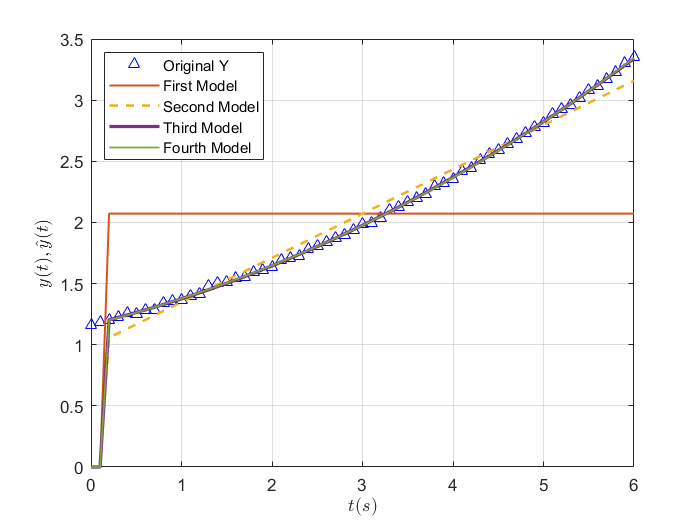

ex_01

**Figura 1: **$y(t)
$e as aproximações $\hat y(t) $ com $\theta^T$ variando. 

Observando a Figura 1, fica claro que à medida em que incrementa-se a complexidade do modelo, menor é a perda associada. No entanto, deve-se analisar a relação de compromisso associada a este incremento, de modo que o modelo não se torne nem subajustado, nem sobreajustado aos dados.

 ***Exemplo 2.3: Sistema Não-Linear***

Considerando $\theta = (a \:\:b_1 \:\: b_2)^T$, $\varphi^T = (-y(t) \:\:u(t) \:\:sin(u(t)))$, o modelo pode ser expresso por:


$$y(t) = \varphi^T(t-1)\theta$$


Diante da linearidade dos parâmetros, a aproximação pode ser obtida por meio do método recursivo de mínimos quadrados. O resultado em termos de $y(t)
$ e $\hat y(t) $ pode ser observado a seguir:

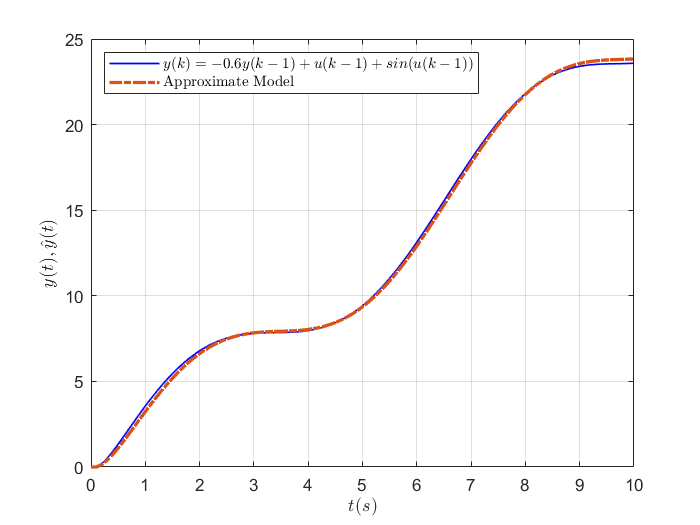

ans = 0.0297

ex_02

**Figura 2: **Sinal real $y(t)$ e sinal aproximado por meio do método de mínimos quadrados. 

Houve uma correta aproximação do modelo não-linear. Mediante um vetor de regressores em função das entradas do sistema $\varphi ^T$e de parâmetros $\theta$, foi possível aproximar $y(t) = \varphi^T\theta$ com um erro quadrático médio próximo de zero. 

***Exemplo 2.5: persistência na excitação - sinal degrau***

Analisando a condição de excitação para conjuntos de dados extensos, tem-se:


$$C_n = \lim_{t\rightarrow\infty}\frac{1}{t}\phi^T\phi = $$

$$\left\lbrack \begin{array}{cccc}
c\left(0\right) & c\left(1\right) & \cdots  & c\left(n-1\right)\\
c\left(1\right) & c\left(0\right) & \cdots  & c\left(n-2\right)\\
\vdots  &  & \ddots  & \\
c\left(n-1\right) & c\left(n-2\right) & \cdots  & c\left(0\right)
\end{array}\right\rbrack$$


Onde c(k) representa as covariâncias empíricas da entrada. Assim:


$$c(k) =  \lim_{t\rightarrow\infty}\frac{1}{t}\sum_{i=1}^{t}u(i)u(i-k)$$


A matriz $C_n$ pode ser escrita como:


$$C_n =  \lim_{t\rightarrow\infty}\frac{1}{t}\sum_{k=1}^{t}\varphi(k)\varphi^T(k)$$


O sinal $u$ só é dito persistentemente excitante de ordem n se, e se somente se:


$$U = \lim_{t\rightarrow\infty}\frac{1}{t}\sum_{i=1}^{t}(A(q)u(k))^2 > 0$$


De forma expandida:


$$U = \lim_{t\rightarrow\infty}\frac{1}{t}\sum_{i=1}^{t}(a_0u(k+n-1)+...+a_{n-1}u(k))^2 = a^TC_na$$


Caso $C_n$ seja positiva definida, o lado direito da equação é positivo para qualquer $a
$, bem como o lado esquerdo. Analisando para uma entrada degrau unitário:


$$C_1 = \lim_{t\rightarrow\infty} \frac{1}{t}\sum_{k=1}^{t}u^2(k) = \lim_{t\rightarrow\infty}\frac{1}{t}\sum_{k=1}^{t}1 = 1$$


Isto significa que o degrau unitário é persistentemente excitante para ordem 1, e não PE, $U \leq 0$, para outras ordens maiores que 1.

***Exemplo 2.10: perda de identificação na presença de realimentação***

Considerando que a estimação dos parâmetros a e b deve se dar por meio de realimentação, $u(t) = -ky(t)$, para o sistema a seguir:


$$y(t+1) + ay(t) = bu(t)$$


Ao multiplicar a equação de realimentação por $\alpha$ e adicionar à equação anterior, tem-se:


$$y(t+1) + (a+\alpha k)y(t) = (b-a)u(t)$$


Assim:


$$\hat a = a + \alpha k \rightarrow \alpha  = \frac{\hat a - a}{k}$$



$$\hat b = b - \alpha$$



$$\hat b = b + \frac{1}{k}(a - \hat a)$$


Sendo assim, múltiplas soluções podem ser obtidas a depender do ganho de realimentação $k$. Portanto, há a ausência de unicidade por conta da variação associada à inclinação da reta $\frac{-1}{k}$. 

De modo a corrigir a perda de identificação devido ao ganho de realimentação, pode-se adicionar ganhos variáveis no tempo na forma:


$$u(t) = -k_1y(t) - k_2y(t-1)$$


Digamos que:


$$\left(t\right)=\left\lbrace \begin{array}{ll}
k_1 \;, & t\le 3\\
k_2 \;, & t>3
\end{array}\right.$$


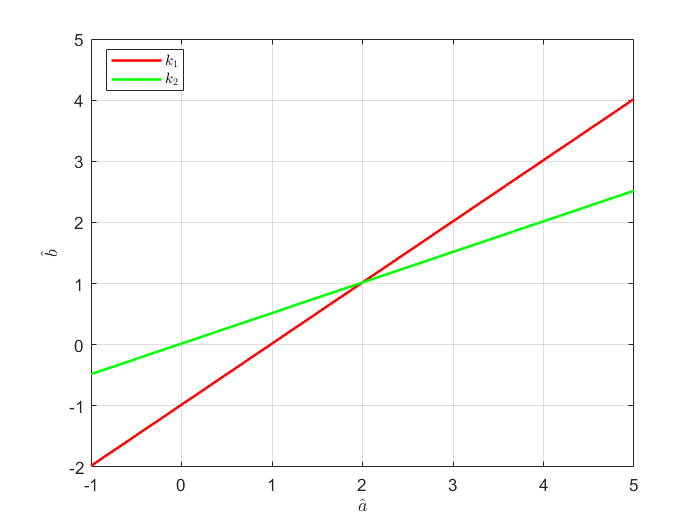

ex_10_b

**Figura 3: **Relação existente entre a e b para realimentação com ganho variável. 

A relação expressa entre $\hat b
$ e $\hat a$ pode ser visualizada acima. Há duas retas com coeficientes angulares diferentes, dependentes do instante de tempo e do ganho de realimentação. No entanto, há um ponto de intersecção destas retas, que indica valores únicos e possíveis para $\hat a =2, \:\:b \approx 1$, o que mitiga o problema da perda de identificação na presença de realimentação.

***Exemplo 2.12: avaliando o sinal de excitação***

Diante de um modelo expresso por: 


$$y(t) + ay(t-1) = bu(t-1) + e(t) + ce(t-1)$$


Os valores de $a $ e $b$ são $-0.8$ e $0.5$, respectivamente. $e(t)$ éum ruído branco gaussiano de média nula e variância $0.5$. Ademais, $c=0$, $P(0) = 100.I$ e $\hat \theta(0) = 0$. Utilizando:


$$\hat \theta  = (\hat a \:\:\:\:\hat b)^T$$



$$\varphi (t-1) = (-y(t-1) \:\: u(t-1))$$


O sinal de entrada $u(t)
$ é defiinido como um pulso unitário em $t=50$. A simulação é feita por mil segundos, onde obtém-se estimativas para $a$ e $b$. O resultado pode ser observado na figura abaixo. 

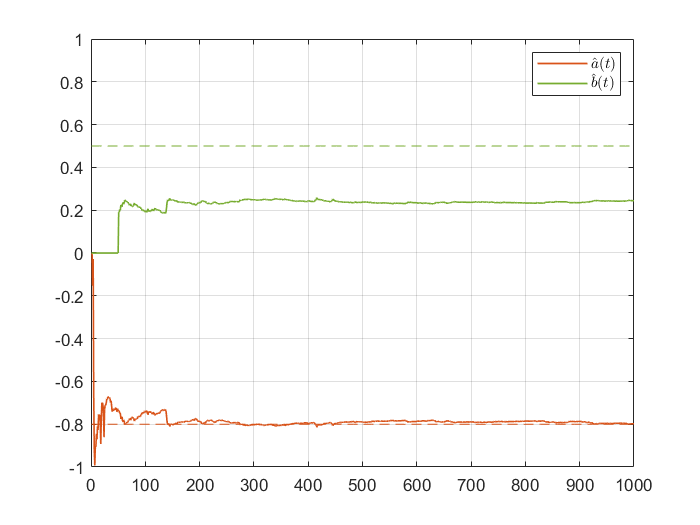

ex_12_a

**Figura 4: **Estimação Evolução temporal dos parâmetros $\hat a\:\:e \:\: \hat b$ aplicando RLS com o sinal de entrada sendo um pulso unitário.

Ao observar a figura acima, constata-se que a estimativa de $\hat b$ distoa do valor esperado, 0.5. Ao aplicar uma onda quadrada com período igual a 100, tem-se:

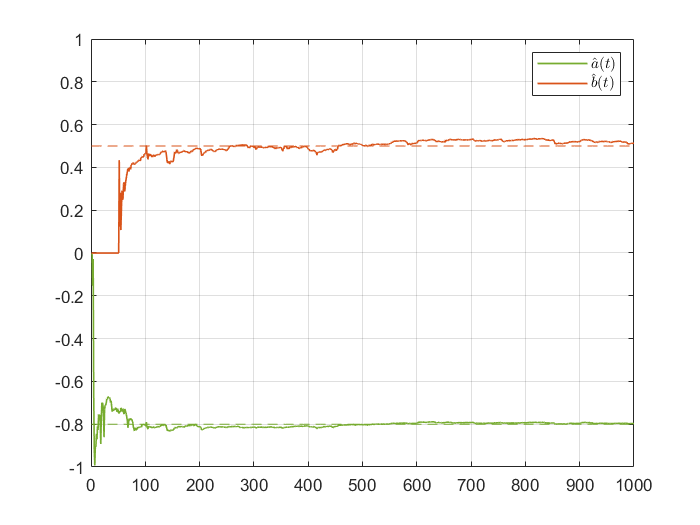

ex_12_b

**Figura 5: **Estimação Evolução temporal dos parâmetros $\hat a\:\:e \:\: \hat b$ aplicando RLS com o sinal de entrada sendo uma onda quadrada. 

Observa-se na Figura 5 que agora a estimativa de $\hat b$ converge para o valor esperado. Embora haja flutuações em torno dos valores reais, os desvios padrão reforçam a convergência da aproximação. 

Desvio padrão para $\hat a$:

std(theta(1,:))

ans = 0.0530

Desvio padrão para $\hat b$:

std(theta(2,:))

ans = 0.1165

***Exemplo 2.13: avaliando a estrutura do modelo***

Neste exemplo, o parâmetro $c$ não é mais nulo, tendo valor $-0.5$. A ideia é avaliar as estimativas para LS (*least squares*) e ELS (Extended Least Squares).  O ruído não é mais gaussiano. As estimativas podem ser observadas na Figura 6.

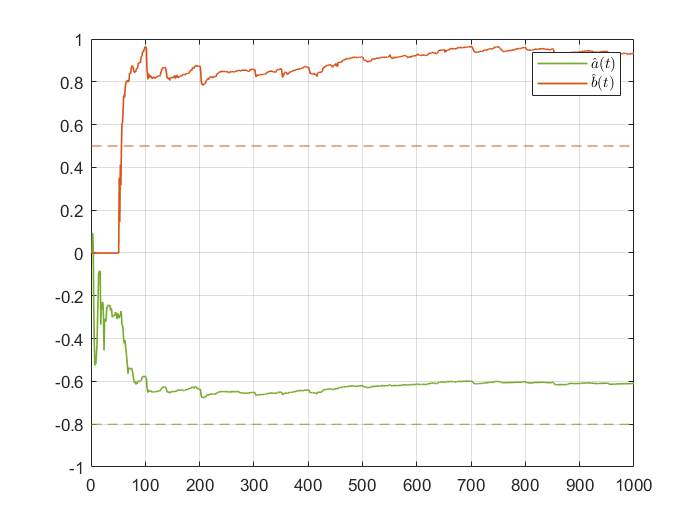

ex_13_a

**Figura 6: **Evolução temporal das estimativas de $\hat a \:\; e \:\; \hat b$ ao aplicar RLS para uma onda quadrática. 

Como pode-se observar, ao considerar um erro não gaussiano e utilizar o método de mínimos quadrados, $E\tilde{\theta} \neq 0$. Isto torna a estimativa dos parâmetros $\hat a$ e $\hat b$ ruim. A alternativa pode ser a utilzação do método de mínimos quadrados extendido. 

No método ELS (*Extended Least Squares) *utiliza-se$\varphi (t-1) = [-y(t-1) \:\:-y(t-n) \:\: u(t-1)\:\:... \:\:u(t-1) \:\: \epsilon(t-1) \:\:... \epsilon(t-n)]^T$, onde $\epsilon = y(t) - \varphi^T(t)\hat \theta(t-1)$. Ou seja, $y(t) = \varphi^T(t)\hat \theta(t-1) + \epsilon $. E isso conduz à estimação dos parâmetros visualizada a seguir:

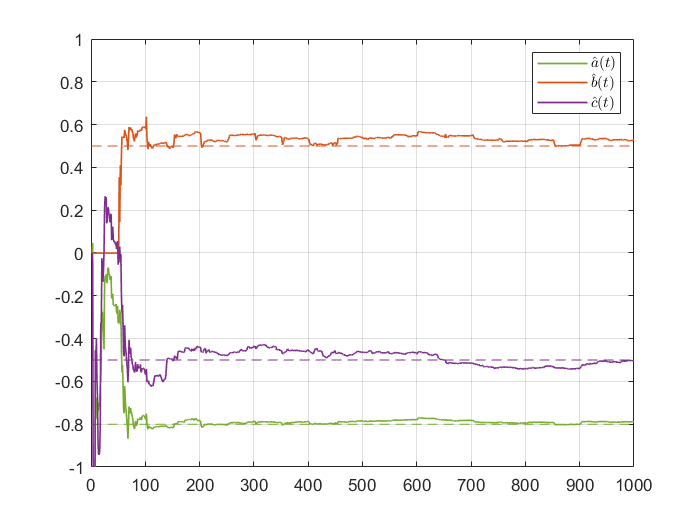

ex_13_b

**Figura 7: **Evolução temporal da estimativa de $\hat a \:\: e \:\: \hat b$ ao empregar ELS para o sinal de entrada sendo uma onda quadrada. 

Os desvios padrão de $\hat a$, $\hat b$ e $\hat c$ são, respectivamente:

std(theta(1,:))

ans = 0.1316

std(theta(2,:))

ans = 0.1198

std(theta(3,:))

ans = 0.1399

O emprego do ELS resolve o problema da ausência de convergência dos parâmetros. 

***Ex. 2.19: Reparametrização***

Considerando a função de transferência


$$G(s) = \frac{\frac{R}{Lc}}{s^2 + \frac{R}{L} + \frac{1}{LC}}$$


Se esta função de transferência descreve uma relação I/O, com $p = \frac{d}{dt}$, do tipo:


$$p^ny + a_1p^{n-1}y + \:\:... \:\: a_ny = b_1p^{n-1}u$$



$$y = \varphi^T(t)\theta^T = [-p^{n-1}y \:\: ... \:\: -y \:\: p^{n-1}u \:\: u]$$


Definindo $\theta_1 = R$, $\theta_2 = \frac{1}{L}$ e $\theta_3=\frac{1}{C}$, a função de transferência se torna:


$$G(s) = \frac{\theta_1 \theta_2 \theta_3}{s^2 + \theta_1\theta_2s + \theta_2\theta_3} = \frac{k_1}{s^2 + k_2 + k_3}$$


A função de transferência discretizada se torna:


$$H(q) = \frac{b_1q + b_2}{q^2 + a_1q + a_2}$$


sim('Simulink Diagrams\ctlsea.slx')

The electrical initial states of your model are forced to zero by the powergui block.


Error evaluating 'StopFcn' callback of block_diagram 'ctlsea'. 
Callback string is 'epex219'

Caused by:
    Error using Relatorio_atv2 (line 13)
    Unrecognized function or variable 'epex219'.

**Figura 8: **Saída estimada $\hat y$ e saída real $y$ a partir da modelagem do circuito. 

A evolução temporal da estimativa indica que os parâmetros da função de transferência foram corretamente estimados. Quaisquer valores relacionados aos componentes do circuito que satisfaçam o formato da função de transferência validam o sistema simulado. 

## Referências bibliográficas 

[1] K. ASTRÖM, B. WITTENMARK.** Adaptive Control**. CRC Press, 2000. ISBN 0486462781